# plotting

SCR_grid = 1.5000

X_R_ratio_grid = 5

fileName = "SCR1_5_XR5"

plotTitle = "SCR: 1.5 X/R: 5"

figName = "SCR1_5_XR5"

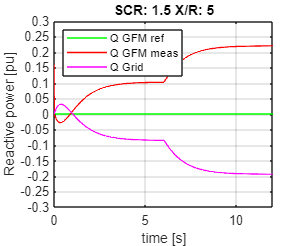

SCR_grid = 2

X_R_ratio_grid = 5

fileName = "SCR2_0_XR5"

plotTitle = "SCR: 2 X/R: 5"

figName = "SCR2_0_XR5"

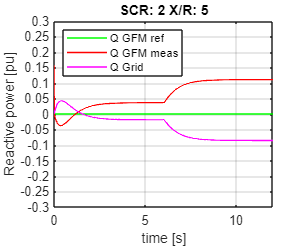

SCR_grid = 3

X_R_ratio_grid = 5

fileName = "SCR3_0_XR5"

plotTitle = "SCR: 3 X/R: 5"

figName = "SCR3_0_XR5"

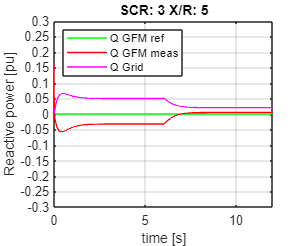

SCR_grid = 3

X_R_ratio_grid = 10

fileName = "SCR3_0_XR10"

plotTitle = "SCR: 3 X/R: 10"

figName = "SCR3_0_XR10"

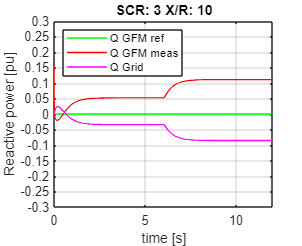

SCR_grid = 5

X_R_ratio_grid = 15

fileName = "SCR5_0_XR15"

plotTitle = "SCR: 5 X/R: 15"

figName = "SCR5_0_XR15"

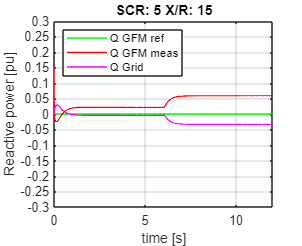


SCR_grid_vec = [1.5 2 3 3 5];
X_R_ratio_grid_vec = [5 5 5 10 15];

n_cases = length(X_R_ratio_grid_vec);
for i = 1:n_cases
    SCR_grid = SCR_grid_vec(i)
    X_R_ratio_grid = X_R_ratio_grid_vec(i) %3;

    fileName = "SCR"+num2str(floor(SCR_grid))+"_" +num2str(mod(SCR_grid,1)*10)+"_" +"XR"+X_R_ratio_grid
    load("sim_data_" + fileName + ".mat","struc_powers")
    
    t = struc_powers.time;
    
    q_LOAD = struc_powers.signals(2).values(:,1);
    q_GRID = struc_powers.signals(2).values(:,2);
    q_GFM = struc_powers.signals(2).values(:,3);
    q_GFM_ref = zeros(size(t));
    
    plotTitle = "SCR: " + SCR_grid + " X/R: " + X_R_ratio_grid
    figName = "SCR"+num2str(floor(SCR_grid))+"_" +num2str(mod(SCR_grid,1)*10)+"_" +"XR"+X_R_ratio_grid
    figure('Name','Reactive_Power'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
    hold on
    grid on
    box on
    
    plot(t,q_GFM_ref,'g-',LineWidth=1);
    plot(t,q_GFM,'r-',LineWidth=1);
    plot(t,q_GRID,'m-',LineWidth=1);
    title(plotTitle,Interpreter="tex")
    
    axis([0 12 -0.3 0.3])
    legend('Q GFM ref', 'Q GFM meas', 'Q Grid' ,Location='northwest') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
    xlabel('time [s]')
    ylabel('Reactive power [pu]')
    ay = gca;
    ay.YTick =-0.3:0.05:0.3;
    
    hold off
    
    set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
    plot_file_name = "Reactive_Power"+ figName +".png";
    exportgraphics(gcf,plot_file_name)
    plot_file_name = "Reactive_Power"+ figName +".pdf";
    
    exportgraphics(gcf,plot_file_name)
end